# $\mathcal{H}_2$** Norm Benchmarks**

We collected a set of problems related with $\mathcal{H}_2$ norm computation. Each section defines system parameters, matrices, delays and computes the $\mathcal{H}_2$ norm of the delay system. You can easily execute all the examples and compare the results with your own algorithms.

## Background

Assuming exponential stability of the delay system, 

$\dot{x}(t) = \sum_{i=0}^{m_A} \ A_i\ x(t-h^A_i)+ \sum_{i=0}^{m_B} \ B_i\ x(t-h^B_i)$,

$y(t) = \sum_{i=0}^{m_C} \ C_i \ x(t-h^C_i)$.

One way to define its $\mathcal{H}_2$ norm is based on the transfer function representation as


$$\|G\|_2: = \sqrt{\frac{1}{2\pi} \int_{-\infty}^\infty trace\left(G^*(j\omega)G(j\omega)\right)dw}$$


where G is the transfer function of the above delay system,

$G(s):=\left( \sum_{i=0}^{mC} C_ie^{-hC_i s}\right)
\left( sI- \sum_{i=0}^{mA} A_ie^{-hA_i s}\right)^{-1}
\left( \sum_{i=0}^{mB} B_ie^{-hB_i s}\right)$.

## Code

Once you define the state-space with delays (ssd) object, you can compute its $\mathcal{H}_2$ norm using **h2norm** function.

% define state-space with delays (type help ssd for more info)
sys = ssd(cat(3,[-2 -1;-1.5 -.5],[0 .5;1 0]),[0 1],[1;-1],0,[2 .2],0,[],0)

sys =   ssd with properties:

       A: [2×2×2 double]
      hA: [0 1]
       B: [2×1 double]
      hB: 0
       C: [2 0.2000]
      hC: 0
       D: 0
      hD: 0
    name: []



% compute H2 norm
h2 = h2norm(sys)

h2 = 1.5687

## Benchmarks

### Example 1 of order 1 - The hot shower problem [1 in p. 820]

The system equations are


$$\dot{x}=-ax(t-h)+bu(t)$$


$y(t)=cx(t)$.

The closed form for the $\mathcal{H}_2$ norm is

$\|G\|_2^2=\frac{c^2b^2}{2a}\frac{cos(ah)}{1-sin(ah)}$.

We compare the analytical $\mathcal{H}_2$ norm results with our numerical ones for $h=0.1k$ where $k=1,\ldots,10$.

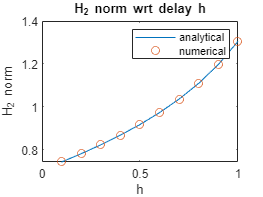

% define system parameters
a = 1; b = 1; c = 1;

% define delay range
h = 0.1:.1:1;

% analytical values
h2 = (c^2*b^2/2/a)*(cos(a*h)./(1-sin(a*h)));

for ct=1:length(h)
    % define delay system for each delay
    sys = ssd(cat(3,0,-a),[0 h(ct)],1,0,1,0,[],[]);
    % compute H2 norm
    happrox(ct) = h2norm(sys);
end

% compare analytical and numerical results
plot(h,sqrt(h2),h,happrox,'o')
xlabel('h')
ylabel('H_2 norm')
title('H_2 norm wrt delay h')
legend('analytical','numerical')

### Example 2.b of order 3 [1 in p. 820-821]

% define system matrices and delays
A0 = [-1  1  2
       1 -3  2
       0  0 -1];  
A1 = [-3  0  1
       1 -2  0
       0  2 -2]*(1/5); 
A2 = [-4  1  0
       0 -2  1
       2  1 -3]*(1/5); 
hA = [0 pi/10 1];
B = [1 1 1]';
hB = 0;
C = [1 1 1];
hC = 0;

% define delay system
sys = ssd(cat(3,A0,A1,A2),hA,B,hB,C,hC,[],[]);

% compute H2 norm
tic
h2 = h2norm(sys)

h2 = 3.8300

time=toc

time = 0.0094

### Example 3 of order 9 [1 in p. 821-822]

% define system matrices and delays
n = 9; h=0.5;
x = ((0:(n-1))/(n-1))*pi;
A0 = ((n+1)/pi)^2*(diag(-2*ones(1,n)) + diag(ones(1,n-1),1) + diag(ones(1,n-1),-1)) + diag(20*ones(1,n));
A1 = diag(-4+x.*(1-exp(x-pi)));
A2 = diag(-.1*ones(1,n));
hA = [0 5*h 6*h];
B = [1;zeros(n-1,1)];
C = ones(1,n);

% define delay system
sys = ssd(cat(3,A0,A1,A2),hA,B,0,C,0,[],[]);

% compute H2 norm
tic
h2 = h2norm(sys)

h2 = 0.2407

time = toc

time = 0.0321

### Heated Rod Example of order 100 [2 in p. 118]

% define system matrices and delays
n = 100;
x = sin(((0:(n-1))/(n-1))*pi);
Delta0 = diag(x);
A0 = ((n-1)/pi)^2*(diag(-2*ones(1,n)) + diag(ones(1,n-1),1) + diag(ones(1,n-1),-1)) -2*Delta0;
A1 = 2*fliplr(Delta0);
hA = [0 1];
B = ones(n,1)/norm(ones(1,n));
C = B';

% define delay system
sys = ssd(cat(3,A0,A1),hA,B,0,C,0,[],[]);
% enable sparse computation option
opt = ssdoptions('Sparse',true);

% compute H2 norm
tic
h2 = h2norm(sys,opt)

h2 = 0.4476

time=toc

time = 0.0714

### Heat Exchanger Example of Order 5 [3 in p. 864]

% define system matrices and delays
A0 = zeros(5); A0(2,1) = 1/3; A0(2,2)= -2/3; A0(3,3)= -1/3; A0(5,4)= -1;
A1 = zeros(5); A1(4,3) = 0.0324;
A2 = zeros(5); A2(1,1) = -0.0714285714;
A3 = zeros(5); A3(4,4) = -0.04;
A4 = zeros(5); A4(2,4) = 1/3;
A5 = zeros(5); A5(1,1) = -0.01219364644; A5(1,2) = -0.05460277319; A5(1,3)= -0.1005215423; A5(1,4) = -0.1290047174;  A5(1,5) = 0.00506339548;
A6 = zeros(5); A6(3,2) = 0.313333333;
A7 = zeros(5); A7(1,2) = 0.01714285714;
hA = [0 2.8 6.5 9.2 13 13.2 18 40];
B = [0.0278571429; zeros(4,1)];
C = eye(5);

% define delay system
sys = ssd(cat(3,A0,A1,A2,A3,A4,A5,A6,A7),hA,B,0,C,0,[],[]);

% compute H2 norm
tic
h2 = h2norm(sys)

h2 = 0.6316

time=toc

time = 0.0241

### Heated Rod Example of order 10000 [3 in p. 865-866]

Same example for n=10000.

% define system matrices and delays
n = 10000;
x = sin(((0:(n-1))/(n-1))*pi);
Delta0 = diag(x);
A0 = ((n-1)/pi)^2*(diag(-2*ones(1,n)) + diag(ones(1,n-1),1) + diag(ones(1,n-1),-1)) -2*Delta0;
A1 = 2*fliplr(Delta0);
hA = [0 1];
B = ones(n,1)/norm(ones(1,n));
C = B';

% define delay system
sys = ssd(cat(3,A0,A1),hA,B,0,C,0,[],[]);

% enable sparse computation option
opt = ssdoptions('Sparse',true,'RelTol',1e-4, 'AbsTol',1e-3);

% compute H2 norm
tic
h2 = h2norm(sys,opt)

h2 = 0.4357

time=toc

time = 6.0491

## References

- E. Jarlebring et al. [Characterizing and computing the H2 norm of time-delay systems by solving the delay Lyapunov equation](https://doi.org/10.1109/TAC.2010.2067510), 2011.

- J. Peeters and W. Michiels, [Computing the H2 norm of large-scale time-delay systems](https://doi.org/10.3182/20130204-3-FR-4031.00121), 2013.

- W. Michiels and B. Zhou, [Computing Delay Lyapunov Matrices and H2 Norms for Large-scale Problems](https://doi.org/10.1137/18M1209842), 2019.